clc;
clear;
close all;

red = readtable('../datasets/winequality-red.csv');
white = readtable('../datasets/winequality-white.csv');

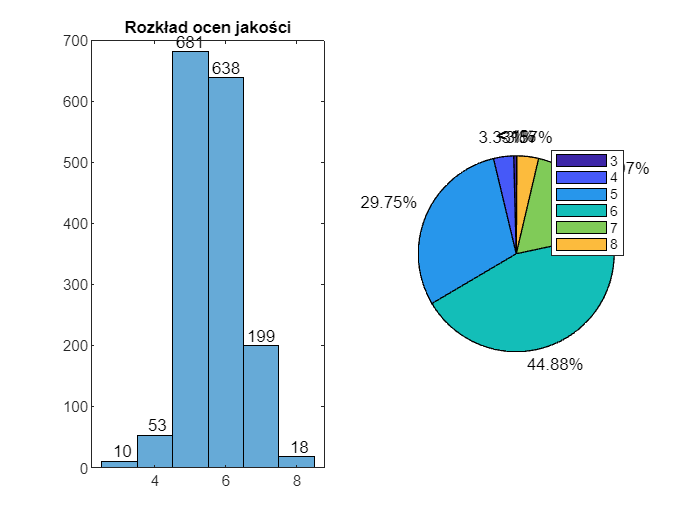

fig1 = figure(1);
fig1.Position(3:4) = [900, 400];

subplot(1,2,1);
hist = histogram(red.quality);
title('Rozkład ocen jakości');

binedges = hist.BinEdges + 0.5;
binvals = hist.Values;

text(binedges(1:end-1), binvals, num2str(binvals'), 'vert', 'bottom', ...
    'horiz', 'center');
subplot(1,2,2);
qint8 = uint8(white.quality);
[Q, QG, QP] = groupcounts(qint8);
pie = pie(Q, '%.2f%%');
legend({'3','4','5','6','7','8'});

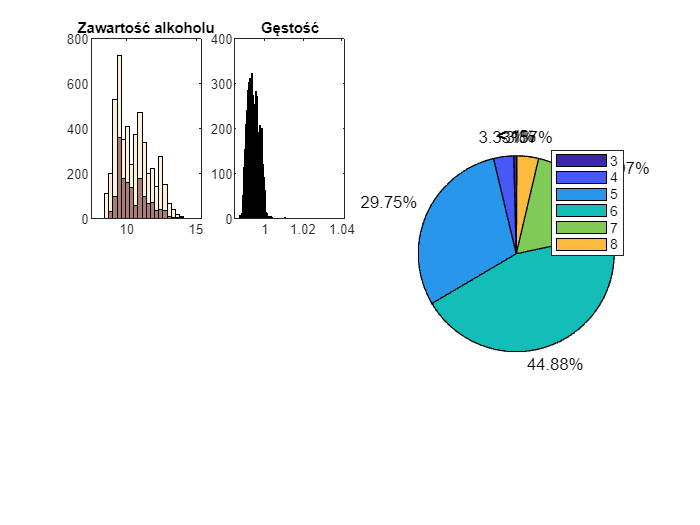

fig2 = figure(2);
fig2.Position = [0, 0, 1500, 600];

subplot(2,4,1);
histogram(white.alcohol,'FaceColor','#f9e8c0');
hold on;
histogram(red.alcohol,'FaceColor','#722F37');
hold off;
title('Zawartość alkoholu');

subplot(2,4,2);
histogram(white.density,'FaceColor','#f9e8c0');
hold on;
histogram(red.density,'FaceColor','#722F37');
hold off;
title('Gęstość');

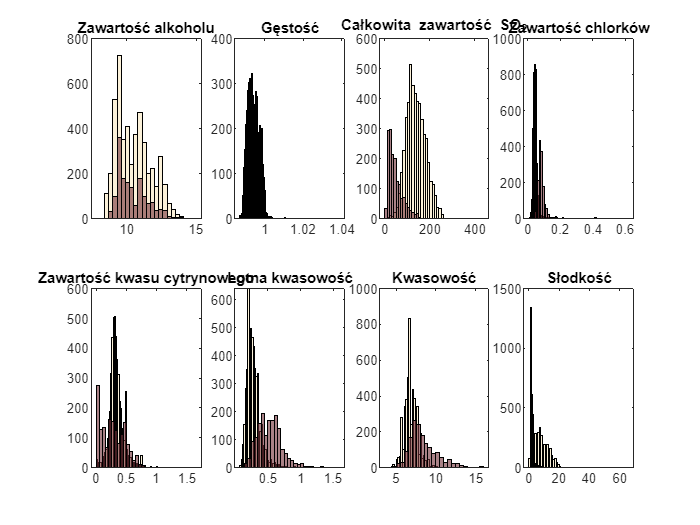


subplot(2,4,3);
histogram(white.totalSulfurDioxide,'FaceColor','#f9e8c0');
hold on;
histogram(red.totalSulfurDioxide,'FaceColor','#722F37');
hold off;
title('Całkowita zawartość SO_2');

subplot(2,4,4);
histogram(white.chlorides,'FaceColor','#f9e8c0');
hold on;
histogram(red.chlorides,'FaceColor','#722F37');
hold off;
title('Zawartość chlorków');

subplot(2,4,5);
histogram(white.citricAcid,'FaceColor','#f9e8c0');
hold on;
histogram(red.citricAcid,'FaceColor','#722F37');
hold off;
title('Zawartość kwasu cytrynowego');

subplot(2,4,6);
histogram(white.volatileAcidity,'FaceColor','#f9e8c0');
hold on;
histogram(red.volatileAcidity,'FaceColor','#722F37');
hold off;
title('Lotna kwasowość');

subplot(2,4,7);
histogram(white.fixedAcidity,'FaceColor','#f9e8c0');
hold on;
histogram(red.fixedAcidity,'FaceColor','#722F37');
hold off;
title('Kwasowość');

subplot(2,4,8);
histogram(white.residualSugar,'FaceColor','#f9e8c0');
hold on;
histogram(red.residualSugar,'FaceColor','#722F37');
hold off;
title('Słodkość');

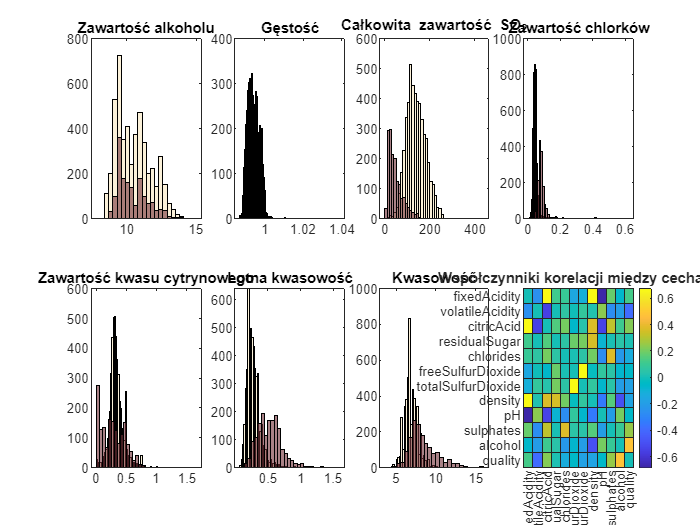

red_ndarray = table2array(red);
red_size = size(red_ndarray);
red_cols = red.Properties.VariableNames;
% diagonala=1 zaburza skalę kolorów gdy najwyższa korelacja~=0.8
red_corr = corrcoef(red_ndarray) - eye(red_size(2));

fig3 = figure(3);
heat = heatmap(red_cols, red_cols, red_corr);
title('Współczynniki korelacji między cechami');
heat.Colormap = parula;